**1. Pulsenergie eines Defibrillators**

Zur Überprüfung der Pulsenergie wurde bei einem Defibrillator an einem 50 Ohm Lastwiderstand eine Spannungsmessung des Pulses vorgenommen. Die Messdaten finden Sie in der Datei Defi50Ohm.csv. 

**Teil - 1: **

**a) Laden Sie die Messdaten ein und stellen Sie die Daten graphisch dar.  **

% Ihre Lösung
dataDefiOhm = readtable('Defi50Ohm.csv');

zeit = dataDefiOhm.x_axis

zeit =    -0.0020
   -0.0020
   -0.0020
   -0.0020
   -0.0020
   -0.0019
   -0.0019
   -0.0019
   -0.0019
   -0.0019


Um = dataDefiOhm.HV

Um =    -8.3477
   -8.3477
   -8.3477
   -8.3477
  -12.3678
   -8.3477
   -8.3477
   -8.3477
   -8.3477
   -8.3477


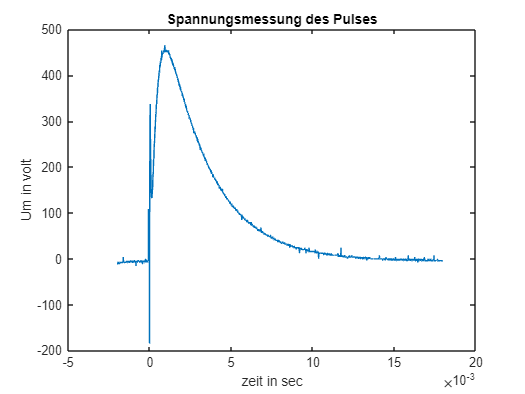

figure()
plot(zeit, Um)
title('Spannungsmessung des Pulses')
xlabel('zeit in sec')
ylabel('Um in volt')

**b) Bestimmen Sie die Leistung aus den Messdaten und stellen Sie diese graphisch dar. **

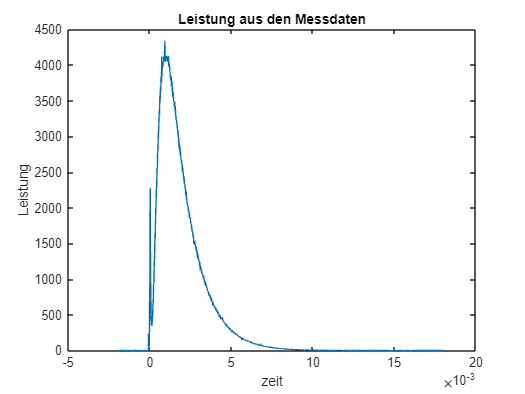

% Ihre Lösung
Res = 50;
Leistung = Um.^2/Res;

figure()
plot(zeit,Leistung)
title('Leistung aus den Messdaten')
xlabel('zeit')
ylabel('Leistung')

**c) Bestimmen Sie abgegebene die Pulsenergie. **

% Ihre Lösung
Pulsenergie = trapz(zeit,Leistung);
fprintf('Abgegebene Pulsenergie: %f', Pulsenergie);

Abgegebene Pulsenergie: 9.560705

### 2. Epidemiologie (SI, SIR, SIRD Modelle)

**Differentialgleichungen **

Das **SI-Modell** (*susceptible-infected-model) *stellt in der mathematischen [Epidemiologie](https://de.wikipedia.org/wiki/Epidemiologie), einem Teilgebiet der [Theoretischen Biologie](https://de.wikipedia.org/wiki/Theoretische_Biologie), einen besonders einfachen Ansatz zur Beschreibung der Ausbreitung von [ansteckenden](https://de.wikipedia.org/wiki/Infektion) Krankheiten dar, wobei alle Gesunden letztendlich infiziert werden.

Dabei bezeichnen zum Zeitpunkt t die Funktionen:

S(t) die gesunden, noch nicht angesteckten Individuen ([*susceptible*](https://de.wikipedia.org/wiki/Biologische_Suszeptibilit%C3%A4t)* individuals* S)   

 I(t) die infizierten, ansteckenden Individuen ([*infectious*](https://de.wikipedia.org/wiki/Infekti%C3%B6s)* individuals* I)

Zur Vereinfachung wird angenommen, dass die Gesamtzahl der betrachteten Menschen N konstant ist und es gilt daher:

N=I(t)+S(t) 

Die Differentialgleichungen für die Veränderungen von S und I über der Zeit mit einer gegebenen Infektionsrate c lauten dann:

dS/dt=-c*I(t)*S(t)

dI/dt=c*I(t)*S(t)

**Aufgaben:**

**a) Lösen Sie mit Hilfe des ode45 Lösers das Gleichungssystem für einen Zeitraum von 3 Monaten für folgende Anfangsbedingungen:**

**Gesamtzahl der betrachteten Personen N=90 000 000. **

**Zahl der anfänglich erkrankten Personen I=1. **

% Ihre Lösung
N_SI = 9e7;
I_SI = 1;
c_SI = 1.5e-7;
S_SI = N_SI - I_SI;
drei_Monate = linspace(0, 90);
odeErgebnis_DM = ode45(@(t, y) SI_Differential_1(t, y, c_SI), drei_Monate, [S_SI; I_SI]);

**b) Stellen Sie den zeitlichen Verlauf der Gesunden und erkrankten Personen in einem Zeitraum von 0 bis 6 Monate graphisch dar. **

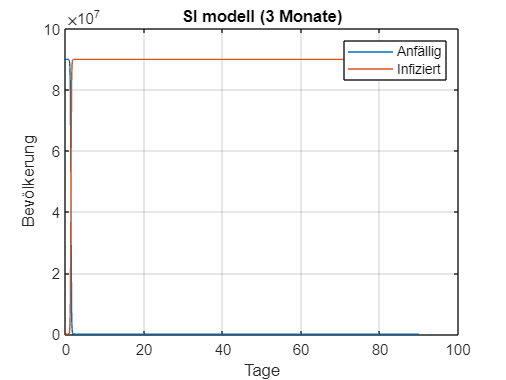

figure;
plot(odeErgebnis_DM.x, odeErgebnis_DM.y(1,:), odeErgebnis_DM.x, odeErgebnis_DM.y(2,:));
xlabel('Tage');
ylabel('Bevölkerung');
legend('Anfällig', 'Infiziert');
title('SI modell (3 Monate)');
grid on;

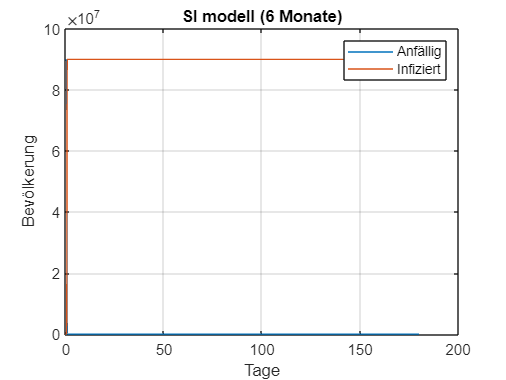

% Für 6 Monate
sechs_Monate = linspace(0, 180);
odeErgebnis_SM = ode45(@(t, y) SI_Differential_1(t, y, c1), sechs_Monate, [S_SI; I_SI]);
figure;
plot(odeErgebnis_SM.x, odeErgebnis_SM.y(1,:), odeErgebnis_SM.x, odeErgebnis_SM.y(2,:));
xlabel('Tage');
ylabel('Bevölkerung');
legend('Anfällig', 'Infiziert');
title('SI modell (6 Monate)');
grid on;

**c) Bei welchem Zeitpunkt sind genausoviele Menschen erkrankt wie gesund? ** 

zeitpunkt = find(abs(odeErgebnis_SM.y(1,:) - odeErgebnis_SM.y(2,:)) == min(abs(odeErgebnis_SM.y(1,:) - odeErgebnis_SM.y(2,:))), 1);
disp(['Zeitpunkt (Tag): ', num2str(odeErgebnis_SM.x(zeitpunkt))]);

Zeitpunkt (Tag): 0.69996


Eine Erweiterung des SI Modells, bei der eine Immunitätsbildung mit eingerechnet wird, stellt das **SIR-Modell ***(susceptible-infected-removed model)* dar. Benannt ist es nach der Gruppeneinteilung der Population in Suszeptible (S), das heißt Ansteckbare, Infizierte (I) und aus dem Infektionsgeschehen entfernte Personen (R), (Recovered). 

Die Differentialgleichungen des SI Modells sind dann für das SIR Modell mit der Veränderung von R über der Zeit ergänzt:

dS/dt=-c*I(t)*S(t)

dI/dt=c*I(t)*S(t)-g*I(t)

dR/dt=g*I(t)

wobei c die Infektionsrate und g die Gesundungsrate ist.

Die Gesamtzahl der betrachteten Menschen N ist dabei konstant ist und es gilt:

N=I(t)+S(t)+R(t). 

**d) Lösen Sie mit Hilfe des ode45 Lösers das Gleichungssystem für einen Zeitraum von 6 Monaten für folgende Anfangsbedingungen:**

**Gesamtzahl der betrachteten Personen N=90 000 000. **

**Zahl der anfänglich erkrankten Personen I=1. **

**Infektionsrate c=3E-7. **

**Gesundungsrate g=1. **

**e) Stellen Sie den zeitlichen Verlauf der gesunden, erkrankten und immunisierten Personen in einem Zeitraum von 0 bis 6 Monate graphisch dar. **

**f) Zu welchem Zeitpunkt ist die maximale Anzahl an Personen erkrankt? **

**g) Um wieviele gleichzeitig erkrankte Personen handelt es sich maximal?  **

% Ihre Lösung


% d)
c = 3E-7;
g = 1

g = 1

SIRMechanismus = @(tSpanne, yWerteReihe) SIR_model(tSpanne,yWerteReihe,c,g)

SIRMechanismus = function_handle with value:
    @(tSpanne,yWerteReihe)SIR_model(tSpanne,yWerteReihe,c,g)


tSegment = [0, 180]

tSegment =      0   180


initialisierung = [89999999; 1; 0]

initialisierung =     89999999
           1
           0


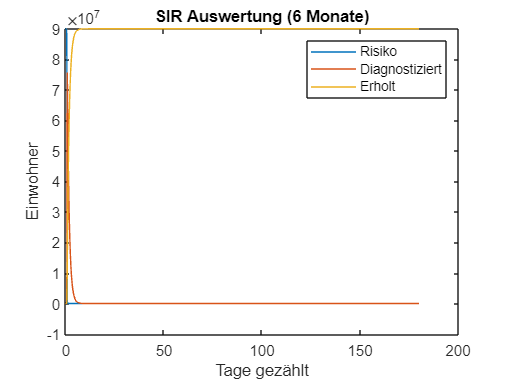

[tSpanne, yWerteReihe] = ode45(SIRMechanismus, tSegment, initialisierung);

% e)
figure();
plot(tSpanne, yWerteReihe(:,1))
hold on;
plot(tSpanne, yWerteReihe(:,2))
hold on;
plot(tSpanne, yWerteReihe(:,3));

title('SIR Auswertung (6 Monate)');
legend('Risiko', 'Diagnostiziert', 'Erholt'); 
xlabel('Tage gezählt');
ylabel('Einwohner');

hoechstInfiziert = max(yWerteReihe(:,2));
% f)
fprintf("Höchstinfektionsrate nach %f Tagen\n", tSpanne(find(yWerteReihe(:,2)==hoechstInfiziert)))

Höchstinfektionsrate nach 0.831711 Tagen



% g)
fprintf("Maximale Erkranktenanzahl: %2.f \n", hoechstInfiziert)

Maximale Erkranktenanzahl: 75673123 


**SIRD - Modell**

Will man in der Simulation die Verstorbenen separat betrachten (statt zur Gruppe *R* hinzuzurechnen), so kann man es zum ***SIRD-Modell*** *(Susceptible-Infected-Recovered-Deceased-Model)* erweitern. Hierbei gehören zur Gruppe *R* nur die Individuen, welche die Krankheit überlebt haben und immun geworden sind, und die Gestorbenen bilden eine eigene Gruppe *D*.

Die Differentialgleichungen des SIR Modells sind dann für das SIRD Modell mit der Veränderung von D über der Zeit ergänzt:

dS/dt=-c*I(t)*S(t)

dI/dt=c*I(t)*S(t)-g*I(t)-m*I(t)

dR/dt=g*I(t)

dD/dt=m*I(t)

wobei m die Mortalitätsrate ist.

Die Gesamtzahl der betrachteten Menschen N ist dabei konstant ist und es gilt:

N=I(t)+S(t)+R(t)+D(t). 

**Teil 2: **

**h) Lösen Sie mit Hilfe des ode45 Lösers das Gleichungssystem für einen Zeitraum von 6 Monaten für folgende Anfangsbedingungen:**

**Gesamtzahl der betrachteten Personen N=90 000 000. **

**Zahl der anfänglich erkrankten Personen I=1. **

**Infektionsrate c=3E-7. **

**Gesundungsrate g=0.8. **

**Mortalitätsrate m=0.2. **

**i) Stellen Sie den zeitlichen Verlauf der gesunden, erkrankten, immunisierten und verstorbenen Personen in einem Zeitraum von 0 bis 6 Monate graphisch dar. **

**j) Ermitteln Sie experimentell, auf welchen Wert die Infektionsrate sinken müsste, damit nicht mehr als ca. 30% der Anzahl aller Personen gleichzeitig krank wird?**

**k) Wann wird unter der ermittelten Infektionsrate das Maximum der Anzahl der Erkrankten erreicht sein?**

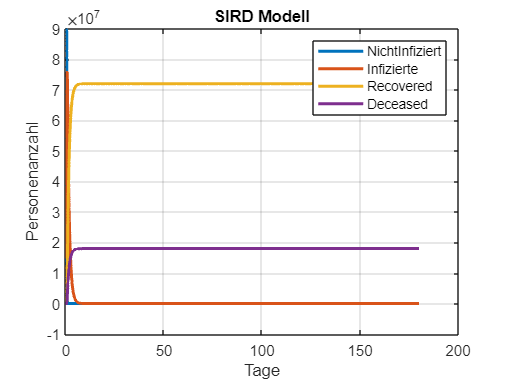

% Ihre Lösung

% h)
c = 3E-7;
g = 0.8;
m = 0.2;

fkt_SIRD = @(t, y) SIRD(t,y,c,g,m);
Anfang_Bedingung = [89999999; 1; 0; 0];
[t, Y] = ode45(fkt_SIRD, [0, 180], Anfang_Bedingung);


% i)
figure();
plot(t, Y(:, 1), 'LineWidth', 2);
hold on;
plot(t, Y(:, 2), 'LineWidth', 2);
hold on;
plot(t, Y(:, 3), 'LineWidth', 2);
hold on;
plot(t, Y(:, 4), 'LineWidth', 2);
title('SIRD Modell');
legend('NichtInfiziert', 'Infizierte', 'Recovered', 'Deceased');
xlabel('Tage');
ylabel('Personenanzahl');
grid on;

% j)
gefundenEins = 0

gefundenEins = 0

rateIdeal = 0;
for faktor = 3E-7:-1E-8:0
    [t, z] = ode45(@(t,z) SIRD(t, z, faktor, 0.8, 0.2), [0,180], [89999999; 1; 0; 0]);
    if max(z(:,2)) < (0.3 * 90000000)
        gefundenEins = 1;
    end
    if gefundenEins == 1
        rateIdeal = faktor;
        break;
    end
end
fprintf("gefunde Rate der Infektion ist : %d", rateIdeal)

gefunde Rate der Infektion ist : 3.000000e-08

% k)
[tInf, yInf] = ode45(@(t,y) SIRD(t,y,rateIdeal, 0.8, 0.2), [0 180], [89999999 1 0 0]);
Zeit_InfRate = tInf(find(yInf(:,2) == max(yInf(:,2))));
display(Zeit_InfRate);

Zeit_InfRate = 11.0794

Ihre Funktionen:

% Ihre Funktionen 



function dy = SI_Differential_1(t, y, rate)
    dy = zeros(2, 1);
    dy(1) = -rate * y(1) * y(2);
    dy(2) = rate * y(1) * y(2);
end

function dy = SIR_model(t, y, c, g)
    St = y(1);
    It = y(2);

    dS = -c * It * St;
    dI = c * It * St - g * It;
    dR = g * It;

    dy = [dS; dI; dR];
end


function dy = SIRD(t,y,c,g,m)
    dy = zeros(4,1); 
    dy(1) = -c * y(2) * y(1);              
    dy(2) = c * y(2) * y(1) - g * y(2) - m * y(2);  
    dy(3) = g * y(2);                     
    dy(4) = m * y(2);                      
end